DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\30mm_Copper_SilverEpoxy\Smith Chart\";
DirectoryName2 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\30mm\Smith Chart\";
DirectoryName3 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\26mm\Smith Chart\";
DirectoryName4 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\24mm\Smith Chart\";

DirectoryName5 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\30mm_Copper_SilverEpoxy\LogMag\";
DirectoryName6 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\30mm\LogMag\";
DirectoryName7 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\26mm\LogMag\";
DirectoryName8 = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Fall 21 Measurements\Pork Polymer 120421\24mm\LogMag\";

DirectoryName

DirectoryName = "C:\Users\chase\Documents\22-23 Senior Project M1 Research\Summer24_Measurements\30mm_Copper_SilverEpoxy\Smith Chart\"

% %paste in your csv or xlsx files here:

FileNames = [
    "PF T1.xlsx";
    "PF T2.xlsx";
    "PF T3.xlsx";
    "PF T4.xlsx";
    "PF T5.xlsx";
    "PF T6.xlsx";
    "PF T7.xlsx";
    "PF T8.xlsx";
    "PF T9.xlsx";
    "PF T10.xlsx";
    "PF T11.xlsx";
    "PF T12.xlsx";
    "PF T13.xlsx";
    "PF T14.xlsx";
    "PF T15.xlsx";
    "PF T16.xlsx";
    "PF T17.xlsx";
    "PF T18.xlsx";
    "PF T19.xlsx";
    "PF T20.xlsx";
    "PF T21.xlsx";
    "PF T22.xlsx";
    "PF T23.xlsx";
    "PF T24.xlsx";
    "PF T25.xlsx";
    "PF T26.xlsx";
    "PF T27.xlsx";
    "PF T28.xlsx";
    "PF T29.xlsx";
    "PF T30.xlsx";
    ];

FileCount = 1:30;

FileNames2 = [
    "PF T1.csv";
    "PF T2.csv";
    "PF T3.csv";
    "PF T4.csv";
    "PF T5.csv";
    "PF T6.csv";
    "PF T7.csv";
    "PF T8.csv";
    "PF T9.csv";
    "PF T10.csv";
    "PF T11.csv";
    "PF T12.csv";
    "PF T13.csv";
    "PF T14.csv";
    "PF T15.csv";
    "PF T16.csv";
    "PF T17.csv";
    "PF T18.csv";
    "PF T19.csv";
    "PF T20.csv";
    "PF T21.csv";
    "PF T22.csv";
    "PF T23.csv";
    "PF T24.csv";
    "PF T25.csv";
    "PF T26.csv";
    "PF T27.csv";
    "PF T28.csv";
    "PF T29.csv";
    "PF T30.csv";
    "PF T31.csv";
    "PF T32.csv";
    "PF T33.csv";
    "PF T34.csv";
    "PF T35.csv";
    "PF T36.csv";
    "PF T37.csv";
    "PF T38.csv";
    "PF T39.csv";
    "PF T40.csv";
    "PF T41.csv";
    "PF T42.csv";
    "PF T43.csv";
    "PF T44.csv";
    "PF T45.csv";
    "PF T46.csv";
    "PF T47.csv";
    "PF T48.csv";
    "PF T49.csv";
    "PF T50.csv";
    "PF T51.csv";
    "PF T52.csv";
    "PF T53.csv";
    "PF T54.csv";
    "PF T55.csv";
    "PF T56.csv";
    "PF T57.csv";
    "PF T58.csv";
    "PF T59.csv";
    "PF T60.csv";
    "PF T61.csv";
    "PF T62.csv";
    "PF T63.csv";
    "PF T64.csv";
    "PF T65.csv";
    "PF T66.csv";
    "PF T67.csv";
    "PF T68.csv";
    "PF T69.csv";
    "PF T70.csv";
    "PF T71.csv";
    "PF T72.csv";
    "PF T73.csv";
    "PF T74.csv";
    "PF T75.csv";
    "PF T76.csv";
    "PF T77.csv";
    "PF T78.csv";
    "PF T79.csv";
    "PF T80.csv";
    "PF T81.csv";
    "PF T82.csv";
    "PF T83.csv";
    "PF T84.csv";
    "PF T85.csv";
    ];

FileCount2 = 1:85;

## S11, Real, and Imaginary Impedance "All in One" Graphs


%PRESENTATION FIGURES_________________________

figure('Position', [1, 1, 600, 500]);
t = tiledlayout(2,3,'TileSpacing','compact','Padding','compact');
% xlabel(t, '|S11| {dB} Distribution at 433 MHz', "FontSize", 11);
ylabel(t, 'Probability Density', "FontSize", 15)

% Tile 1
nexttile([2 2])
[~, ~, z] = plotStanDist(DirectoryName5, FileNames2, FileCount2);
pd = normalFit(z)

pd =   NormalDistribution

  Normal distribution
       mu = -10.7104   [-11.31, -10.1109]
    sigma =   2.7796   [2.41539, 3.27417]


    sigma = pd.sigma;
    mu = pd.mu;

    dim = [0.1 .59 1 .4];
    str = {"Mean = " + mu + "dB", "Standard Deviation = " + sigma + "dB"};
    a = annotation('textbox', dim, 'String',str,'FitBoxToText','on');
    a.FontSize = 11;
xlabel(sprintf('|S_{11}| dB'),'interpreter','tex', 'FontSize', 15);
xlim([-30 -5])

% Span across two rows and columns
nexttile
[x, ~, ~] = plotStanDist(DirectoryName, FileNames2, FileCount2);
pd = normalFit(x)

pd =   NormalDistribution

  Normal distribution
       mu = 31.7768   [30.918, 32.6356]
    sigma = 3.98145   [3.45976, 4.68987]


    % sigma = pd.sigma;
    % mu = pd.mu;
    % 
    % dim = [0.75 .5 0.2 .4];
    % str = {"Mean = " + mu + "Ω", "Standard Deviation = " + sigma + "Ω"};
    % a = annotation('textbox', dim, 'String',str,'FitBoxToText','on');
    % a.FontSize = 11;
xlabel(sprintf('Real Impedance'),'interpreter','tex', 'FontSize', 15);
% xlim([30 70])
% legend('S11', 'Normal Fit', 'Location', 'northeastoutside');

% Last tile
nexttile
[~, y, ~] = plotStanDist(DirectoryName, FileNames2, FileCount2);
pd = normalFit(y)

pd =   NormalDistribution

  Normal distribution
       mu = 1.28525   [-3.26041, 5.83091]
    sigma = 21.0745   [18.3131, 24.8243]


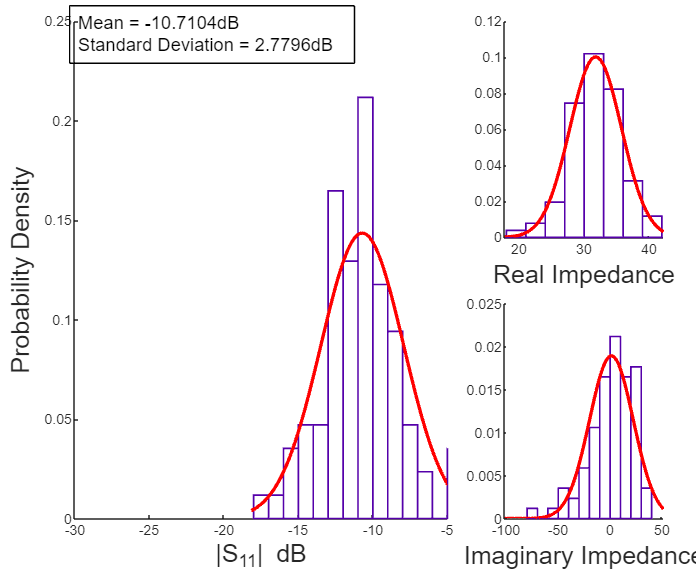

%     sigma = pd.sigma;
%     mu = pd.mu;
%     dim = [0.75 .4 1 0];
%     str = {"Mean = " + mu + "i Ω", "Standard Deviation = " + sigma + "i Ω"};
%     a = annotation('textbox', dim, 'String',str,'FitBoxToText','on');
%     a.FontSize = 11;
xlabel(sprintf('Imaginary Impedance'),'interpreter','tex', 'FontSize', 15);

%______________________________Presentation END____________________________



## Smith Chart

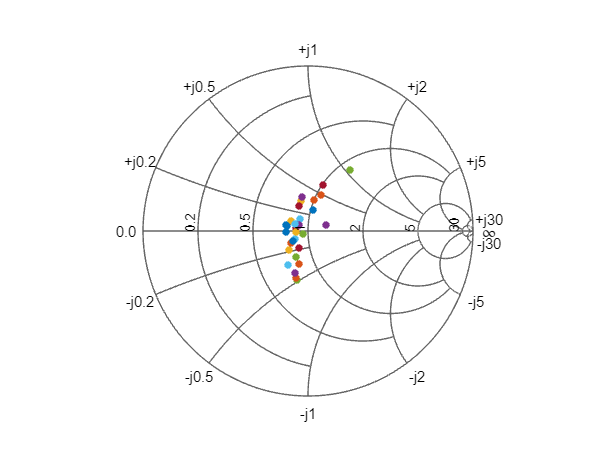


figure('Color', [1,1,1]);
plotSmith(DirectoryName4, FileNames, FileCount);

% xlabel(" (d) ", 'FontWeight', 'bold', 'FontSize', 11);


## Single Freq Spread All measurements

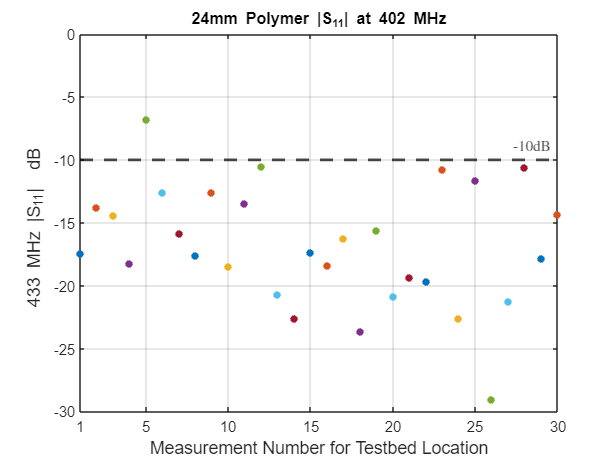

figure;
plot402S11(DirectoryName8, FileNames, FileCount);
title("24mm Polymer |S_{11}| at 402 MHz");
xlabel(" Measurement Number for Testbed Location ", 'FontSize', 12);
ylabel(" 433 MHz |S_{11}| { dB } ", "FontSize", 12);
yline(-10, 'k--', '-10dB', "LineWidth", 2, 'Interpreter', 'latex', 'LabelOrientation', 'horizontal');

## VSWR

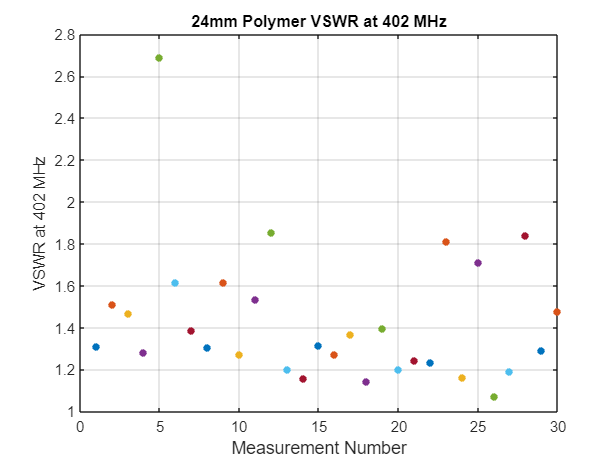


figure;
[VSWR, absRefCo] = S11dBVSWRdot(DirectoryName8, FileNames, FileCount);
title("24mm Polymer VSWR at 402 MHz");
xlabel(" Measurement Number ", 'FontSize', 12);
ylabel("VSWR at 402 MHz");

function plot402S11(DirectoryName, FileNames, FileCount) %S11 dB at 433 MHz

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        S11_dB = VNA_Zdata(103,2);
        plot(loopFiles,S11_dB, '.', 'MarkerSize', 15);
        ylim([-30 0])
        xticks([1 5 10 15 20 25 30])
        xlim([1 30])
        grid on;
        hold on;
    end
end

function [y] = plotSmith(DirectoryName, FileNames, FileCount) %Smith Chart Version for single frequency.

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        Freq = VNA_Zdata(103,1);
        Real = VNA_Zdata(103,2);
        Imag = VNA_Zdata(103,3);

        i = sqrt(-1);
        Z = Real + (Imag*i);
        Z0 = 50; %Characteristic impedance 50 0hm's
        S11 = (Z-Z0)./(Z+Z0); %<--- complex number %This IS NOT the magnitude.
        y = smithplot(Freq, S11,'.', 'MarkerSize', 15);    
        hold on;
    end
end


function  [x, y, z] = plotStanDist(DirectoryName, FileNames, FileCount) %S11 dB at 433 MHz

    x = zeros(1,30); %creates (N,M) N row, M column array (matrix).
    y = zeros(1,30); %creates (N,M) N row, M column array (matrix).
    z = zeros(1,30); %creates (N,M) N row, M column array (matrix).

    for loopFiles = FileCount
        VNA_Zdata = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        x(1, loopFiles) = VNA_Zdata(103,2); %Adding data to the array made above. For smith real impedance
        y(1, loopFiles) = VNA_Zdata(103,3); %Adding data to the array made above. For Smith imaginary impedance
        z(1, loopFiles) = VNA_Zdata(103,2); %Adding data to the array made above. For |S11| dB
    end

    % pd = fitdist(z, 'Normal');
    % ci99 = paramci(pd, 'Alpha', 0.01);
    % histfit(z);
end

function [VSWR, absRefCo] = S11dBVSWRdot(DirectoryName, FileNames, FileCount)

    for loopFiles = FileCount
        VNA_data = readmatrix(strcat(DirectoryName,FileNames(loopFiles,:)));
        S11_dB = VNA_data(103,2);
        absRefCo = 10^(S11_dB/20);
        VSWR = (1+absRefCo)./(1-absRefCo);
        plot(loopFiles, VSWR, '.', 'MarkerSize', 15);
        % ylim([0 2])
        grid on;
        hold on;
    end
end